# Complex Fourier Series

**Learning Goals**

- Recall Euler's formula.

## Euler's Formula

Possibly one of the most surprising formulas in mathematics, Euler's formula relates exponentials to trigonometric functions using complex numbers:


$$e^{i \theta} = \cos \theta + i \sin \theta$$


Pictured in the complex plane, Euler's formula traces out a circle. 

**Task. **Slowly drag the slider below from 0 to 360 to trace out a circle using Euler's formula.

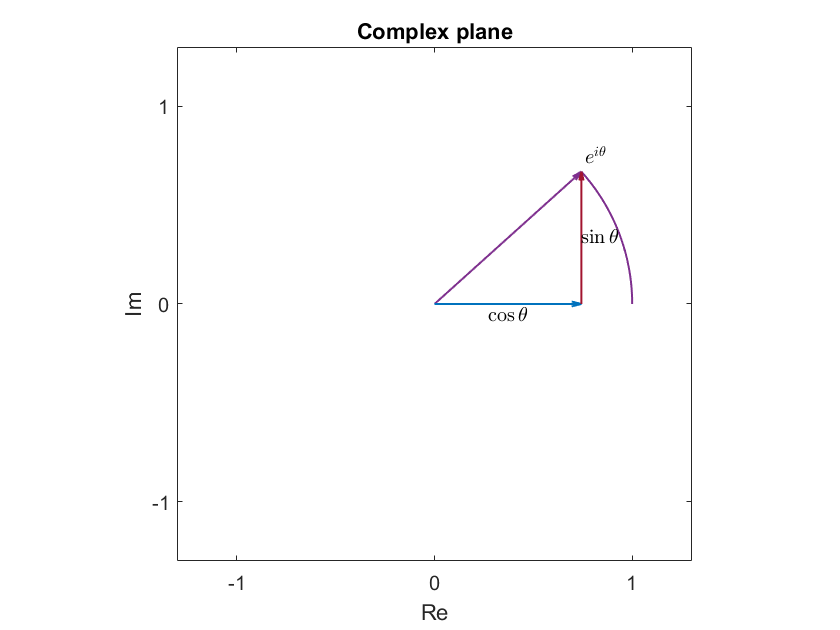

thetad = 42; % In degrees
complexCircle(thetad); % Helper function that generates the plot

By adjusting the slider, you were changing the angle $\theta$ with time. In the complex plane, that traced out a circle. Plotting each component separately with respect to time will produce two plots: the real component will trace out a cosine curve and the imaginary component will trace out a sine curve.

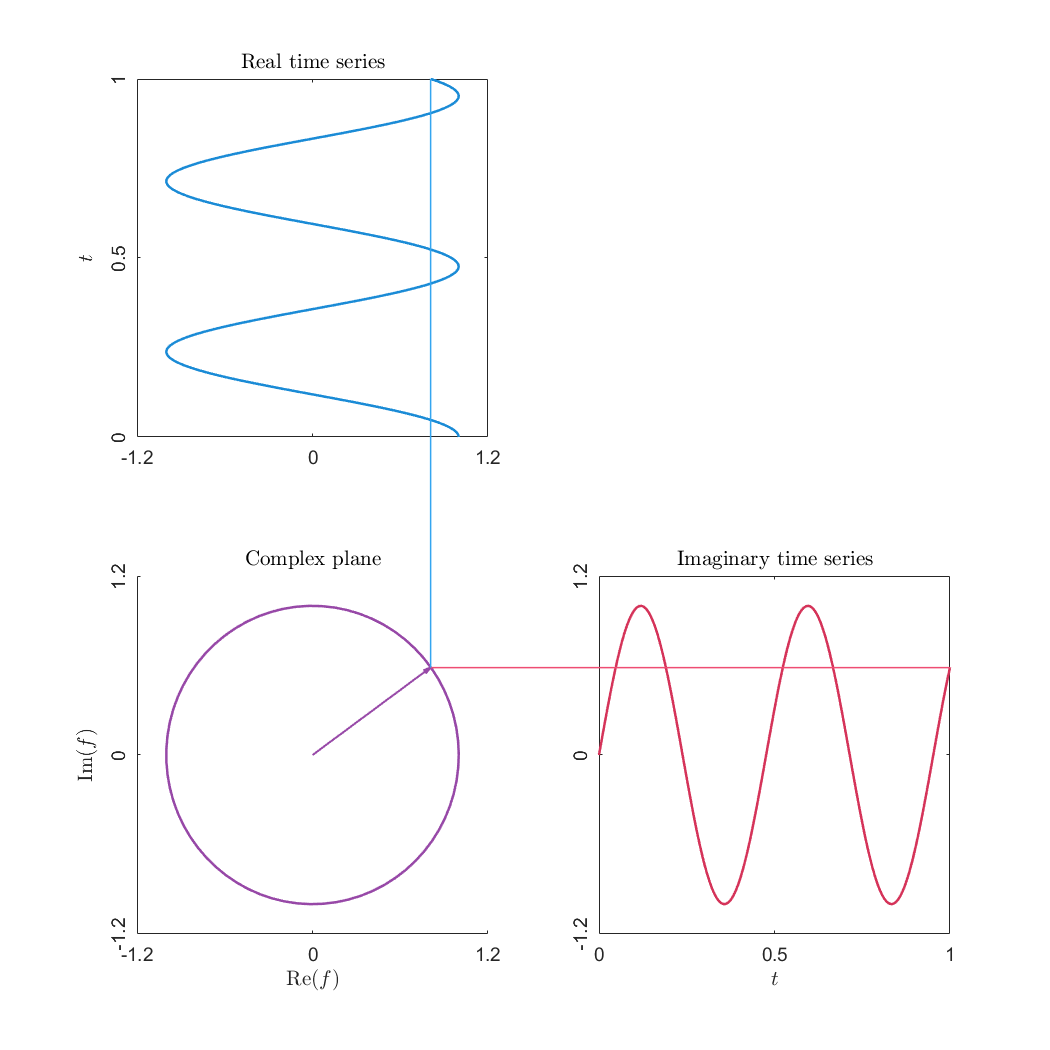

freq = 2.1; % In Hz
traceSineCosine(freq); % Helper function that traces the curve

### Definition

Using Euler's formula, the Fourier series can be written in terms of complex exponentials (instead of sines and cosines):


$$f(t) = \sum_{-\infty}^\infty c_n e^{ \frac{i n \pi}{L} t}$$


This is commonly referred to as the complex Fourier series. The coefficients of the complex Fourier series can be evaluated using the integral


$$c_n = \frac{1}{2L} \int_{-L}^{L} y(t) e^{ -\frac{i n \pi}{L} t} dt$$


** Example. **Compute the complex Fourier series for


$$y(t) = 3 \cos( 2 \pi t)$$


assuming that $L = 0.5$ s. To compute the coefficient for $n = 1$, apply the formula, and rewrite the cosine in terms of complex exponentials.


$$\begin{array}{rl}
c_1 &= \frac{1}{2(0.5)} \int_{-0.5}^{0.5} 3 \cos( 2 \pi t) e^{ -\frac{i \pi}{0.5} t} dt
\\
&= 3 \int_{-0.5}^{0.5} \frac{e^{ 2 \pi i t} + e^{- 2 \pi i t} }{2}  e^{ -2 i \pi t} dt
\\
&= \frac{3}{2} \int_{-0.5}^{0.5} 1+ e^{- 4 \pi i t} dt
\\
&= \frac{3}{2}
\\
\end{array}$$


The other coefficients will be zero except $n = -1$, since the original function has only a single frequency. Try computing the integral for $n = -1$. You should find that $c_{-1} = 3/2$.Therefore the complex Fourier series has coefficients $c_n = 0$ except $c_1 = 3/2$ and $c_{-1} = 3/2$. Run this section to see a plot of the coefficients.

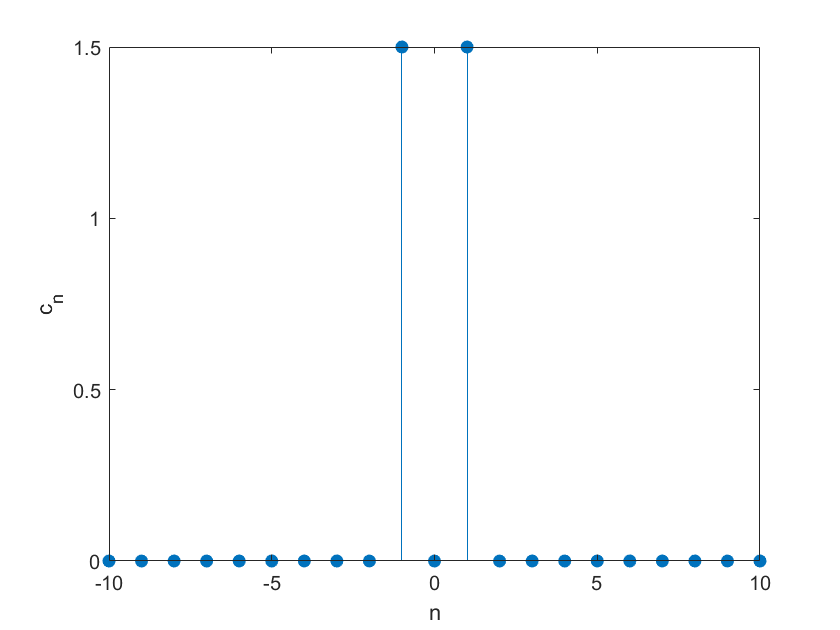

% Create the coefficient vector
freq = -10:10;
cn = zeros(size(freq));
cn([10,12]) = 3/2;
% Create the plot
figure
stem(freq,cn,'filled')
xlabel("n")
ylabel("c_n")

At this point, it may seem that a complex function has been created from a real function. However, for this series to accurately reproduce $y(t)$ it should not have a complex part. To verify that $f(t)$ accurately reproduces $y$, you can apply Euler's formula.


$$f(t) = \frac{3}{2} e^{-2 \pi i t} +  \frac{3}{2} e^{2 \pi i t}$$


... [incomplete]....

** Example. **Compute the complex Fourier series for


$$y(t) = \sin ( 2 \pi t)$$


assuming that $L = 0.5$ s. To compute the coefficient for $n = 1$, apply the formula, and rewrite the cosine in terms of complex exponentials.


$$\begin{array}{rl}
c_1 &= \frac{1}{2(0.5)} \int_{-0.5}^{0.5} \sin( 2 \pi t) e^{ -\frac{i \pi}{0.5} t} dt
\\
&= \int_{-0.5}^{0.5} \frac{e^{ 2 \pi i t} - e^{- 2 \pi i t} }{2i}  e^{ -2 i \pi t} dt
\\
&= \frac{1}{2i} \int_{-0.5}^{0.5} 1 - e^{- 4 \pi i t} dt
\\
&= \frac{1}{2i} = -2i
\\
\end{array}$$


The negative coefficient is


$$\begin{array}{rl}
c_{-1} &= \frac{1}{2(0.5)} \int_{-0.5}^{0.5} \sin( 2 \pi t) e^{ \frac{i \pi}{0.5} t} dt
\\
&= \int_{-0.5}^{0.5} \frac{e^{ 2 \pi i t} - e^{- 2 \pi i t} }{2i}  e^{ 2 i \pi t} dt
\\
&= \frac{1}{2i} \int_{-0.5}^{0.5}   e^{- 4 \pi i t} - 1 dt
\\
&= \frac{1}{2i} = 2i
\\
\end{array}$$


function checkEx1Task1(a1,a2,b1,b2)
    isEqualCheck([a1,a2,b1,b2],[3,2,0,1])
end

function checkEx1Task2(A1,A2,phi1,phi2)
    isEqualCheck([A1,A2,phi1,phi2],[3,sqrt(5),0,atan2(1,2)])
end

function isEqualCheck(userSubmission,correctAnswer)
% This function checks if two results are equal and displays feedback
    if( isequal(userSubmission, correctAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
    end
end

function complexCircle(theta)
    % This function traces out a circle in the complex plane
    % With labels for Euler's formula
    
    f = exp(1i*theta * pi/180);
    thetaVec = 0:theta;
    fc = exp(1i*thetaVec*pi/180);
    
    colors = lines(7);
    
    figure
    quiver(0,0,real(f),imag(f),"off","LineWidth",1,"color",colors(4,:))
    hold on
    plot(real(fc),imag(fc),"LineWidth",1,"color",colors(4,:))
    quiver(0,0,real(f),0,"off","LineWidth",1,"color",colors(1,:))
    quiver(real(f),0,0,imag(f),"off","LineWidth",1,"color",colors(7,:))
    text(real(f)/2,0,"$\cos \theta$","Interpreter","latex",...
        "VerticalAlignment","top","HorizontalAlignment","center")
    text(real(f),imag(f)/2,"$\sin \theta$","Interpreter","latex",...
        "VerticalAlignment","middle","HorizontalAlignment","left")
    text(real(f)*1.1,imag(f)*1.1,"$e^{i \theta}$","Interpreter","latex",...
        "VerticalAlignment","middle","HorizontalAlignment","center")
    hold off
    
    axis equal
    axis(1.3*[-1 1 -1 1])
    xlabel("Re")
    ylabel("Im")
    title("Complex plane")
    xticks([-1,0,1])
    yticks([-1,0,1])
end


function pFig = figPos(ax,p)
    % This function computes the position of points
    % in the figure

    axUnits = ax.Units;
    ax.Units = 'normalized';
    pos = ax.InnerPosition;

    % Shifted so that the origin is at the lower-left corner
    x = p(1)-ax.XLim(1);
    y = p(2)-ax.YLim(1);
    
    % Compute the position of the point in the figure
    xFig = x*(pos(3))/(ax.XLim(2) - ax.XLim(1)) + pos(1);
    yFig = y*(pos(4))/(ax.YLim(2) - ax.YLim(1)) + pos(2);
    
    pFig = [xFig,yFig];
    ax.Units = axUnits;
end

function traceSineCosine(freq)
    
    % This defines the function
    Nt = 150;
    tvec = linspace(0,1,Nt);
    fvec = exp(freq*2*pi*1i*tvec);
    
    % Appearance settings
    timeColors = [     0    0.4470    0.7410;
        0.7350    0.1000    0.2500;
        0.4940    0.1840    0.5560]+0.1;
    
    imLims = 1.2*[-1,1]; % Im limits on complex plane
    reLims = 1.2*[-1,1]; % Re limits on complex plane       
    
    lwSeries = 1.25;
    lw = 0.75;

    % Set up the axes
    figure("position",[1,1,700,700])
    ax1 = subplot(2,2,3);
    ax2 = subplot(2,2,1);
    ax3 = subplot(2,2,4);
    
    % Plots
    reLine = plot(ax2,tvec*0,tvec,...
        "linewidth",lwSeries,"color",timeColors(1,:));
    imLine = plot(ax3,tvec,tvec*0,...
        "linewidth",lwSeries,"color",timeColors(2,:));     
    hold(ax1,"on")
    cmplxLine = plot(ax1,tvec*0,tvec*0,...
        "linewidth",lwSeries,"color",timeColors(3,:));
    arrow = quiver(ax1,0,0,0,0,"off","LineWidth",1,"color",timeColors(3,:));
    hold(ax1,"off")

    % Change graph appearance: complex plane
    set(ax1,"XLimMode","manual","YLimMode","manual")
    xlim(ax1,reLims)
    ylim(ax1,imLims)
    xticks(ax1,[reLims(1), mean(reLims),reLims(2)])
    yticks(ax1,[imLims(1), mean(imLims),imLims(2)])
    xlabel(ax1,"Re$(f)$","interpreter","latex")
    ylabel(ax1,"Im$(f)$","interpreter","latex")
    title(ax1,"Complex plane","Interpreter","latex")
    ytickangle(ax1,90)
    
    % Graph appearance: real 
    set(ax2,"XLimMode","manual","YLimMode","manual")
    xlim(ax2,reLims)
    ylim(ax2,[tvec(1),tvec(end)])
    xticks(ax2,[reLims(1), mean(reLims),reLims(2)])
    yticks(ax2,[tvec(1), mean(tvec),tvec(end)])
    ylabel(ax2,"$t$","interpreter","latex")
    title(ax2,"Real time series","Interpreter","latex")
    ytickangle(ax2,90)
    
    % Graph appearance: imaginary
    set(ax3,"XLimMode","manual","YLimMode","manual")
    ylim(ax3,imLims)
    xlim(ax3,[tvec(1),tvec(end)])
    yticks(ax3,[imLims(1), mean(imLims),imLims(2)])
    xticks(ax3,[tvec(1), mean(tvec),tvec(end)])
    xlabel(ax3,"$t$","interpreter","latex")
    title(ax3,"Imaginary time series","Interpreter","latex")
    ytickangle(ax3,90);
    
    crossLine1 = annotation("line",[0,0],[0,0],...
        "LineStyle","-","LineWidth",lw,"color",timeColors(1,:)+0.1);
    crossLine2 = annotation("line",[0,0],[0,0],...
        "LineStyle","-","LineWidth",lw,"color",timeColors(2,:)+0.1);
    
    for k = 1:numel(tvec)
        t = tvec(k);
        f = fvec(k);
        
        % This code creates the connecting lines
        pComplex = [real(f),imag(f)];
        pReal = [real(f),t];
        pImag = [t,imag(f)];
        
        pCFig = figPos(ax1,pComplex);
        pRFig = figPos(ax2,pReal);
        pIFig = figPos(ax3,pImag);
        
        % Update the curves
        cmplxLine.XData = real(fvec(1:k));
        cmplxLine.YData = imag(fvec(1:k));
        
        reLine.XData = real(fvec(1:k));
        reLine.YData = tvec(1:k);
        
        imLine.XData = tvec(1:k);
        imLine.YData = imag(fvec(1:k));
        
        arrow.UData = real(fvec(k));
        arrow.VData = imag(fvec(k));
        
        % Create annotation between the axes
        p1 = [real(f),imag(f)];
        p2 = [real(f),t];
        p3 = [t,imag(f)];
        
        p1Fig = figPos(ax1,p1);
        p2Fig = figPos(ax2,p2);
        p3Fig = figPos(ax3,p3);
        
        crossLine1.X = [p1Fig(1),p2Fig(1)];
        crossLine1.Y = [p1Fig(2),p2Fig(2)];
        
        crossLine2.X = [p1Fig(1),p3Fig(1)];
        crossLine2.Y = [p1Fig(2),p3Fig(2)];

    
        drawnow
    end
end